### 1 Выбор модели

Загружаем интересующую нас модель

mdl_KR5;
robot = KR5;
%Включим вывод графиков
plots = true;

Выведем параметры Денавита - Хартенберга

robot.display;

 
robot = 
 
Kuka KR5:: 6 axis, RRRRRR, stdDH, slowRNE                        
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        0.4|       0.18|     1.5708|          0|
|  2|         q2|      0.135|        0.6|    3.14159|          0|
|  3|         q3|      0.135|       0.12|    -1.5708|          0|
|  4|         q4|       0.62|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 0.115), RPY/xyz = (0, 0, 0) deg              
 


Сравним конфигурацию реального робота и представление модели (ниже есть вывод графика), и убедимся, что кинематически они совпадают.

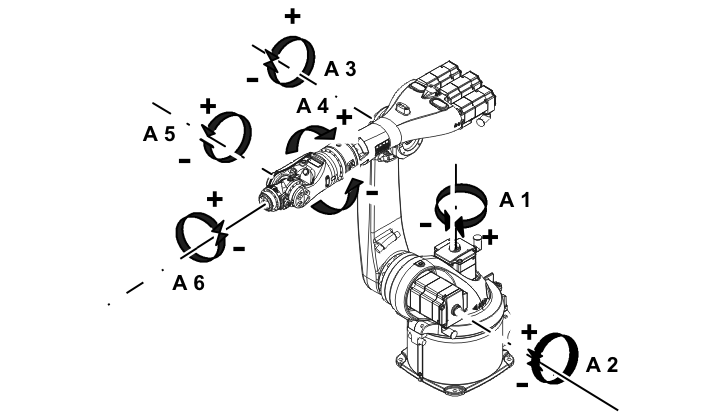

### 2. Задание параметров, определяющих динамику робота

Общий вес робота Kuka KR5, согласно документации, равен 127 килограмм. На основе габаритов робота на чертеже сделаем предположение о распределении общей массы по каждому из звеньев

robot.links(1).m = 40;
robot.links(2).m = 30;
robot.links(3).m = 30;
robot.links(4).m = 14;
robot.links(5).m = 8;
robot.links(6).m = 5;


Зададим центры масс для каждого звена в геометрическом центре модели

этого звена

robot.links(1).r = [0 0 robot.links(1).a/2];
robot.links(2).r = [0 robot.links(2).a/2 0];
robot.links(3).r = [0 robot.links(3).a/2 0];
robot.links(4).r = [0 -robot.links(4).a/2 0];
robot.links(5).r = [0 robot.links(5).a/2 0];
robot.links(6).r = [0 0 robot.links(6).a/2];


Выбираем тензоры инерции относительно центров масс. Предположим, что каждое звено имеет цилиндрическую форму. 

r = 0.2; % Радиус цилиндрического звена
robot.links(1).I = [robot.links(1).m * (3 * r^2 + robot.links(1).a^2)  / 12 0 0;
                    0 robot.links(1).m * (3 * r^2 +robot.links(1).a^2)  / 12  0;
                    0 0 robot.links(1).m * robot.links(1).a^2 /2;];

robot.links(2).I = [robot.links(2).m * robot.links(2).a^2 / 12 0 0;
                    0 0 0;
                    0 0 robot.links(2).m * robot.links(2).a^2 /12;];

robot.links(3).I = [robot.links(3).m * robot.links(3).a^2 / 12 0 0;
                    0 0 0;
                    0 0 robot.links(3).m * robot.links(3).a^2 /12;];

robot.links(4).I = [robot.links(4).m * (3 * r^2 +robot.links(4).a^2)  / 12 0 0;
                    0 robot.links(4).m * (3 * r^2 +robot.links(4).a^2)  / 12  0;
                    0 0 robot.links(4).m * robot.links(4).a^2 /2;];

robot.links(5).I = [robot.links(5).m * robot.links(5).a^2 / 12 0 0;
                    0 0 0;
                    0 0 robot.links(5).m * robot.links(5).a^2 /12;];

robot.links(6).I = [robot.links(6).m * (3 * r^2 +robot.links(6).a^2)  / 12 0 0;
                    0 robot.links(6).m * (3 * r^2 +robot.links(6).a^2)  / 12  0;
                    0 0 robot.links(6).m * robot.links(6).a^2 /2;];


Выставим ограничения по обобщённым координатам:

robot.links(1).qlim = [deg2rad(-155) deg2rad(155)];
robot.links(2).qlim = [deg2rad(-180) deg2rad(65)];
robot.links(3).qlim = [deg2rad(-15) deg2rad(158)];
robot.links(4).qlim = [deg2rad(-350) deg2rad(350)];
robot.links(5).qlim = [deg2rad(-130) deg2rad(130)];
robot.links(6).qlim = [deg2rad(-350), deg2rad(350)];


Установим моменты инерции моторов:

robot.links(1).Jm = 0.05;
robot.links(2).Jm = 0.05;
robot.links(3).Jm = 0.05;
robot.links(4).Jm = 0.05;
robot.links(5).Jm = 0.05;
robot.links(6).Jm = 0.05;

Передаточные числа редукторов:

robot.links(1).G = 1;
robot.links(2).G = 1;
robot.links(3).G = 1;
robot.links(4).G = 1;
robot.links(5).G = 1;
robot.links(6).G = 1;

### 3. Зададим произвольные начальный и конечный вектор обобщённых координат робота:

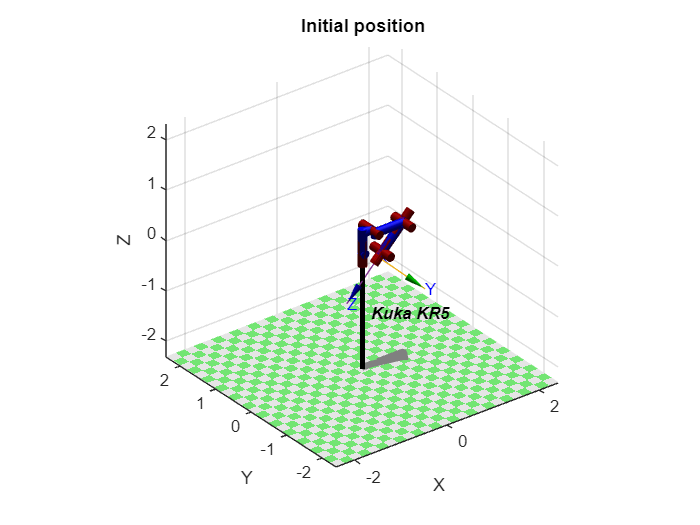

q_init = [0 0 pi/4 0 0 -pi/4];
q_final = [pi/2 pi/4 0 -pi/2 0 0];
if plots == true
    f1 = figure;
    figure(f1)
    title("Initial position")
    robot.plot(q_init,'jointdiam', 1)
end  

В пакете **rvctools **вывод моделей робота на график реализован таким образом, что при изменение положения робота (экземляра класса SerialLink), изменяются и положения этого объекта на всех других открытых окнах. Что бы отобразить начальное и конечное положения и анимацию, будем работать с копиями оригинального робота.

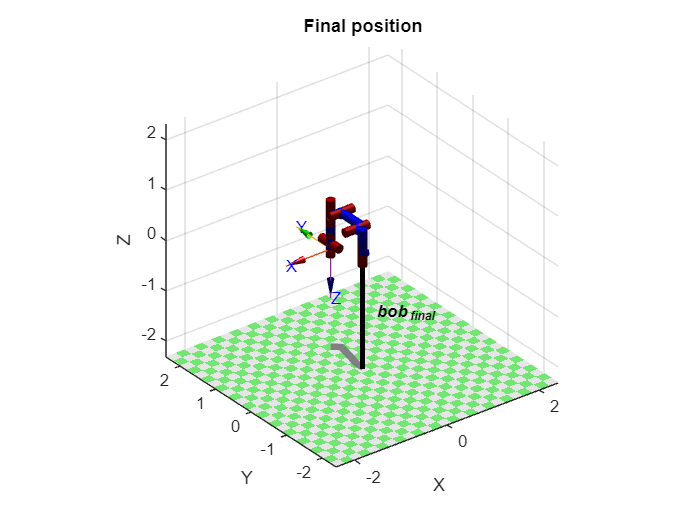

if plots == true
    f2 = figure;
    bob = SerialLink(robot, 'name', 'bob_{final}');
    figure(f2)
    title("Final position")
    bob.plot([pi/2 0 0 -pi/2 0 0],'jointdiam', 1)
end

### 4. Спланируем траекторию движения от начальной к конечной точкам

t = [0:.05:2];
[Q,Qt,Qtt] = jtraj(q_init, q_final, t);

Функция *jtraj() *возвращает матрицы обобщённых координат, скоростей и ускорений в каждой точке траектории.

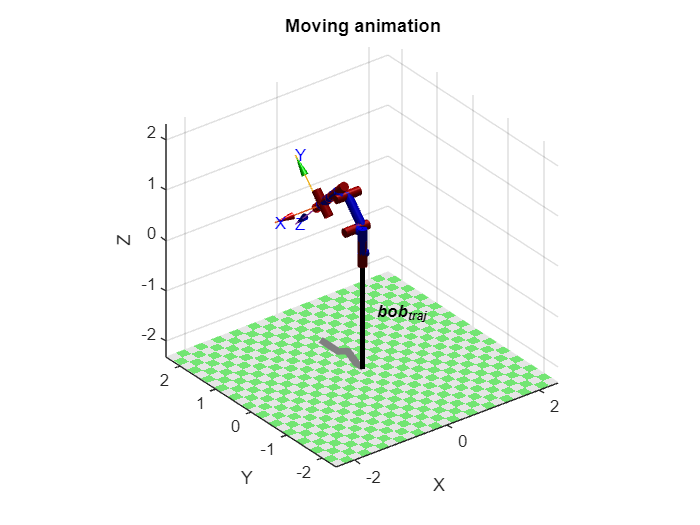

if plots == true 
    f3 = figure;
    bob_traj = SerialLink(robot, 'name', 'bob_{traj}');
    figure(f3);
    title("Moving animation");
    bob_traj.plot(Q,'jointdiam', 1)
end

### 5. Решим обратную задачу динамики методом Ньютона - Эйлера для разных случаев:

 Для решения будем использовать функцию пакета rvctools rne()

#### а) Ненулевые скорости и ускорения.

f4 = figure;
figure(f4)
tau = robot.rne(Q, Qt, Qtt);

Матрица инерций:

M = robot.inertia(Q);

Вектор гравитационных сил:

G = robot.gravload(Q);

Матрица Кориолисовых сил

C = robot.coriolis(Q, Qt);

subplot(3,1,1);
plot(t, tau(:,1:6)); xlabel('Time (s)'); ylabel('Joint torque (Nm)');
legend(["Link 1","Link 2","Link 3","Link 4","Link 5","Link 6"]);
title("$\dot{q} \neq 0, \ddot{q} \neq 0$", 'Interpreter','latex');


#### б) Ненулевые скорости и пренебрежимо малые ускорения.


tau = robot.rne(Q, Qt, Qtt.*1e-15);

Матрица инерций:

M = robot.inertia(Q);

Вектор гравитационных сил:

G = robot.gravload(Q);

Матрица Кориолисовых сил

C = robot.coriolis(Q, Qt);
subplot(3,1,2);
plot(t, tau(:,1:6)); xlabel('Time (s)'); ylabel('Joint torque (Nm)')
legend(["Link 1","Link 2","Link 3","Link 4","Link 5","Link 6"]);
title("$\dot{q} \neq 0, \ddot{q} \approx 0$", 'Interpreter','latex');


#### в) Нулевые скоости и ускорения.


[qshape1, qshape2] = size(Q, 1, 2);
tau = robot.rne(Q, zeros(qshape1, qshape2), zeros(qshape1, qshape2));

Матрица инерций:

M = robot.inertia(Q);

Вектор гравитационных сил:

G = robot.gravload(Q);

Матрица Кориолисовых сил

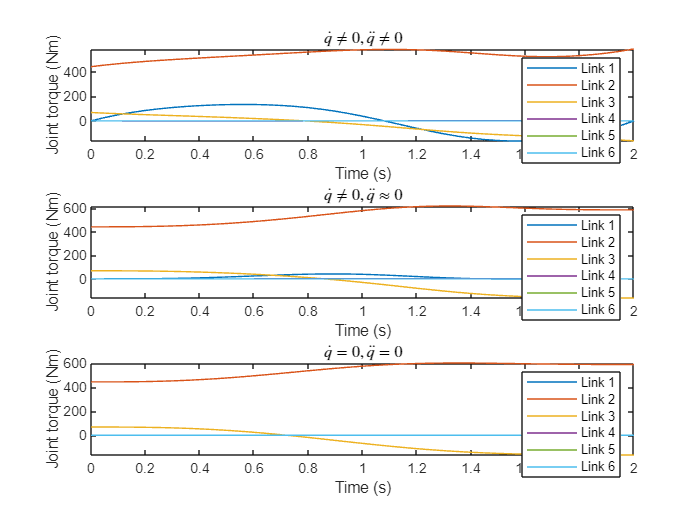

C = robot.coriolis(Q, zeros(qshape1, qshape2));

subplot(3,1,3);
plot(t, tau(:,1:6 )); xlabel('Time (s)'); ylabel('Joint torque (Nm)')
legend(["Link 1","Link 2","Link 3","Link 4","Link 5","Link 6"]);
title("$\dot{q} = 0, \ddot{q} = 0$", 'Interpreter','latex');